clc;clear;close all force;

**PARTE 0 **

load input.mat
RA="225295";
[L, B, a, w0, E] = dados_de_entrada(RA, T);

**PARTE 1**

[A, Qz, yc, Izz] = calcular_propriedades_geometricas(a, B);

Localização do centroide (yc): 0.18261
Valor esperado para o centroide: 0.18261
Valor do primeiro momento de área (integral simples): 0.012109
Valor do segundo momento de área (integral simples + teorema dos eixos paralelos): 0.00097512
Valor esperado para o segundo momento de área: 0.00097512



fprintf('Área da seção transversal: %.4f\n', A);

Área da seção transversal: 0.0663


fprintf('Primeiro momento de Área, Qz: %.4f\n', Qz);

Primeiro momento de Área, Qz: 0.0121


fprintf('Localização do centroide, yc: %.4f\n', yc);

Localização do centroide, yc: 0.1826


fprintf('Segundo momento de Área, Izz: %.4f\n', Izz);

Segundo momento de Área, Izz: 0.0010


Nesse caso, a integral dupla é mais complexa de implementar, pois envolve uma integração em duas variáveis. No entanto, geralmente fornecerá resultados mais precisos, pois considera uma função mais complexa da seção transversal. A integral simples é uma aproximação que assume uma função constante para a seção transversal.

Podemos comparar os resultados obtidos utilizando a integral dupla e a integral simples + teorema dos eixos paralelos para verificar qual método é mais simples de calcular e se os resultados estão próximos ao valor esperado.

**PARTE 2**

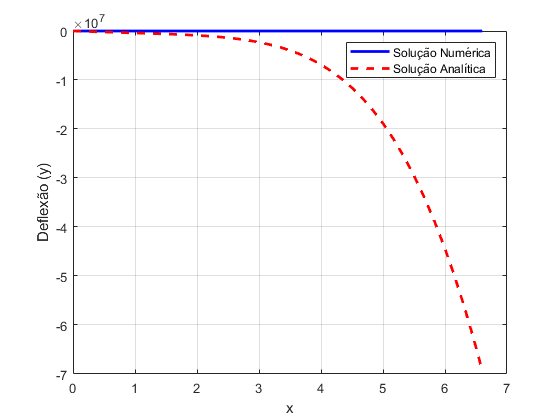

% Definição das equações diferenciais de primeira ordem
dydx = @(x, y, u) y;
dudx = @(x, y, u) -(1/(E*Izz)) * (-(w0/3*L)*x.^3 + ((2*w0)/3*L)*(x-L/2).^3 + (1/4)*w0*L*x);
dvzdx = @(x, y, u) u;

% Condições iniciais
x0 = 0;
y0 = 0;
u0 = 0;
vz0 = 0;
initial_conditions = [y0; u0; vz0];

% Resolver as equações diferenciais
[x, sol] = ode45(@(x, y) [dydx(x, y(1), y(2)); dudx(x, y(1), y(2)); dvzdx(x, y(1), y(2))], [x0 L], initial_conditions);

% Extrair a deflexão da solução
y_numerical = sol(:, 1);

% Plotar a solução numérica e analítica
plot(x, y_numerical, 'b-', 'LineWidth', 2);
hold on;
% Calcular a solução analítica esperada
y_analytical = -(w0/60*L)*x.^5 + (w0/30*L)*sing((x-L/2),5) + (1/24)*w0*L*x.^3 - (5/192)*w0*L^3*x;
plot(x, y_analytical, 'r--', 'LineWidth', 2);
xlabel('x');
ylabel('Deflexão (y)');
legend('Solução Numérica', 'Solução Analítica');
grid on;

function [L, B, a, w0, E] = dados_de_entrada(RA, T)
    % Buscar linha correspondente ao RA na tabela
    linha = find(strcmp(T.RA, RA));

    % Extrair os valores dos parÃ¢metros
    L = T.L(linha);
    B = T.B(linha);
    a = T.a(linha);
    w0 = T.w0(linha);
    E = T.E(linha);
end


function [A, Qz, yc, Izz] = calcular_propriedades_geometricas(a, B)
    % Cálculo da área da seção transversal
    A = integral(@(z) a*cos(pi*z/B), -B/2, B/2);
    
    % Cálculo do primeiro momento de área
    Qz = (a^2/2) * integral(@(z) cos(pi*z/B).^2, -B/2, B/2);
    
    % Cálculo da localização do centroide
    yc = Qz / A;
    
    % Valor esperado para o centroide
    yc_esperado = pi*a/8;
    
    % Exibição dos resultados
    disp(['Localização do centroide (yc): ' num2str(yc)]);
    disp(['Valor esperado para o centroide: ' num2str(yc_esperado)]);
    % Cálculo do primeiro momento de área utilizando integral dupla
    
    % Qz_integral_dupla = integral2(@(y, z) y, 0, @(z) a*cos(pi*z/B), -B/2, B/2);
    
    % Exibição dos resultados
    % disp(['Valor do primeiro momento de área (integral dupla): ' num2str(Qz_integral_dupla)]);
    disp(['Valor do primeiro momento de área (integral simples): ' num2str(Qz)]);
    yc = pi*a/8; % Valor dado para yc

    % Cálculo do segundo momento de área utilizando integral dupla
    % Izz_integral_dupla = integral2(@(y, z) y.^2, -yc, @(z) acos(pi*z/B)-yc, -B/2, B/2);
    
    % Exibição do valor do segundo momento de área obtido da integral dupla
    % disp(['Valor do segundo momento de área (integral dupla): ' num2str(Izz_integral_dupla)]);
    % Cálculo do segundo momento de área utilizando a integral simples e o teorema dos eixos paralelos
    Izz_integral_simples = (a^3/3) * integral(@(z) cos(pi*z/B).^3, -B/2, B/2) - A*(yc^2);
    
    % Exibição do valor do segundo momento de área obtido da integral simples e do teorema dos eixos paralelos
    disp(['Valor do segundo momento de área (integral simples + teorema dos eixos paralelos): ' num2str(Izz_integral_simples)]);
    
    % Valor esperado para o segundo momento de área
    Izz_esperado = ((128-9*pi^2)*B*a^3) / (288*pi);
    
    % Exibição do valor esperado para o segundo momento de área
    disp(['Valor esperado para o segundo momento de área: ' num2str(Izz_esperado)]);
    Izz=Izz_integral_simples;
end

function y = sing(x,n) 
    %singularity function y = <x-a>^n 
    if n>=0 
        y = x.^n.*(x>=0); 
    else 
        y = 0*x; 
    end 
end